# Lab Session 1

**Multibody System Dynamics**

This session deals with kinematics of multibody systems. We will work on two fundamental aspects:

- **The position problem**

- **The Newton–Raphson algorithm**

## The Position Problem

The multibody system has a set of $n$ dependent coordinates ${\bf q}$ with a set of $r$ constraint equations


$${\bf \Phi} ({\bf q}) = {\bf 0}$$


Then, a set of $m = n - r$ independent coordinates ${\bf s}({\bf q})$ parametrizes the motion of the constraint system.

The position problem aims at finding the value of the dependent coordinates ${\bf q}$ that satysfy the constraint equations ${\bf \Phi} ({\bf q}) = {\bf 0}$. Additionally, an initial value for the dependent coordinates ${\bf s (q)} = {\bf s}_0$ can also be specified.

Therefore, we need to solve the following nonlinear equation:


$${\bf f(q)} = \left[\matrix{ {\bf \Phi (q)} \cr {\bf s (q)} - {\bf s}_0 } \right] = {\bf 0}$$


### Newton–Raphson Algorithm

To solve the nonlinear equation ${\bf f(q) = 0}$ using the Newton–Raphson algorithm, we need a linear approximation of the constraints equation about a configuration ${\bf q}_0$


$${\bf f(q)} \approx {\bf f} ({\bf q}_0) + {\bf J}({\bf q}_0) ({\bf q} - {\bf q}_0)$$


where ${\bf J(q)}$ is the $n\times n$ Jacobian matrix of the coordinate transformation. Then, if we set ${\bf f(q) = 0}$, the following iterative algorithm can be defined


$${\bf q}_{k+1} = {\bf q}_{k} - {\bf J}({\bf q}_{k})^{-1} {\bf f} ({\bf q}_{k})$$


Therefore, starting from an initial configuration ${\bf q}_0$, we can perform iterations until we find the configuration ${\bf q}$ that satisfies the nonlienar equation ${\bf f(q) = 0}$ under a certain tolerance $\| {\bf q}_{k+1} - {\bf q}_{k}\| < \varepsilon$.

## Double Pendulum

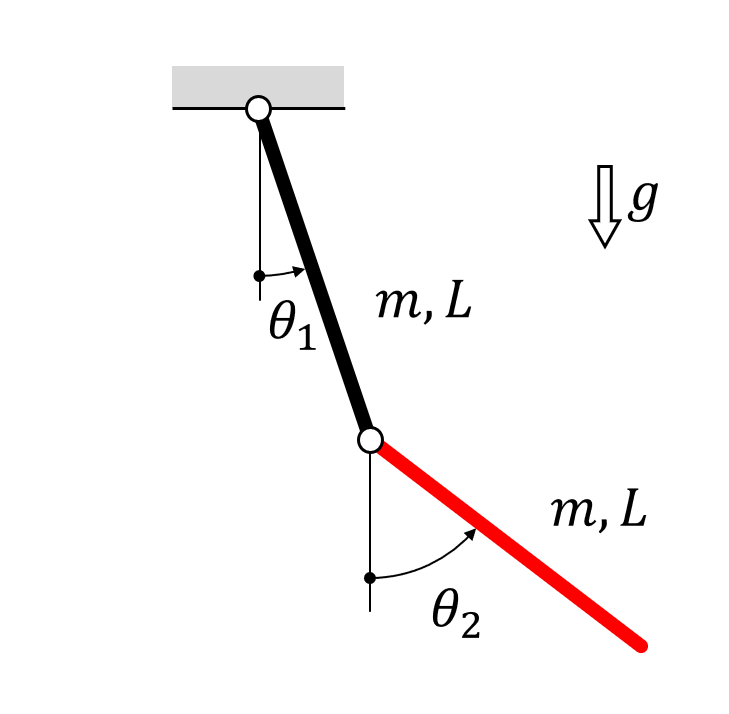

### Model

The `Model` defines the properties of the `Body`'s, `Joints`'s and `Coordinate`'s. Here, we use the predefined double pendulum model in the `/models` folder:

% model = DoublePendulum();

### Viewer

The `Viewer` is used to disply the model's geometry in a MATLAB figure window

% viewer = Viewer(model);
% viewer.initViewer();
% viewer.axes.XLim = [-2,+2];
% viewer.axes.YLim = [-2,+2];
% viewer.showAxes(true);

Or simply initialize the `Viewer` like this:

% viewer = model.initViewer([-2,+2],[-2,+2]);

**Note: **Every time the `Model` is modified, the `Viewer` has to be updated:

% model.bodySet(1).position(1) = 0.5; % first body x coordinate
% model.bodySet(2).position(1) = 0.8; % second body x coordinate
% viewer.update();

*Note that the bodies do not satisfy the joints yet.*

### System

The `System` is the data structure of the dynamics of the multibody system. It contains the generalized coordinates and velocities, and the **dynamic equations**.

% system = System(model);

The information in the `Model` is used to calculate the system's data. Therefore, the `System` has to be udated before making any calculations, and the `Model` has to be updated after:

% system.update();
% do calculation with system ...
% model.update();
% viewer.update();

# Assignment

### **1. Solve the position problem**

Write a function to solve the possition problem using the **Newton–Rapson algorithm**. You must specify the desired value for the independent coordinates ${\bf s}_0$.

**Note: **Use the function at the end of this file.

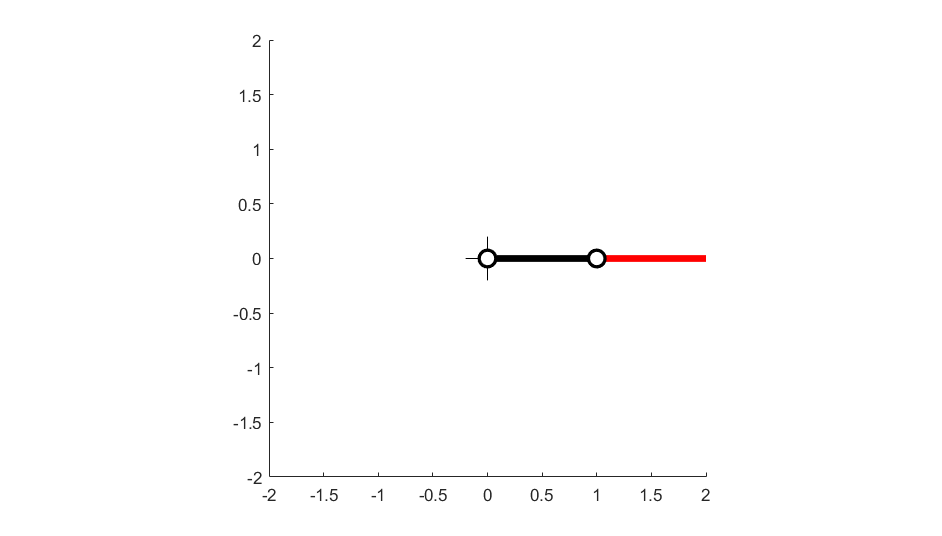

model = DoublePendulum();
viewer = model.initViewer([-2,+2],[-2,+2]);
viewer.showAxes(true);
system = System(model);

% Solve position problem
indepCoord = [pi/2; pi/2];
solvePositionProblem(system, indepCoord);

viewer.update();

### **2. Animation**

Write an algorithm that animates the coordinates of the double pendulum. Use the following lines as starting point:

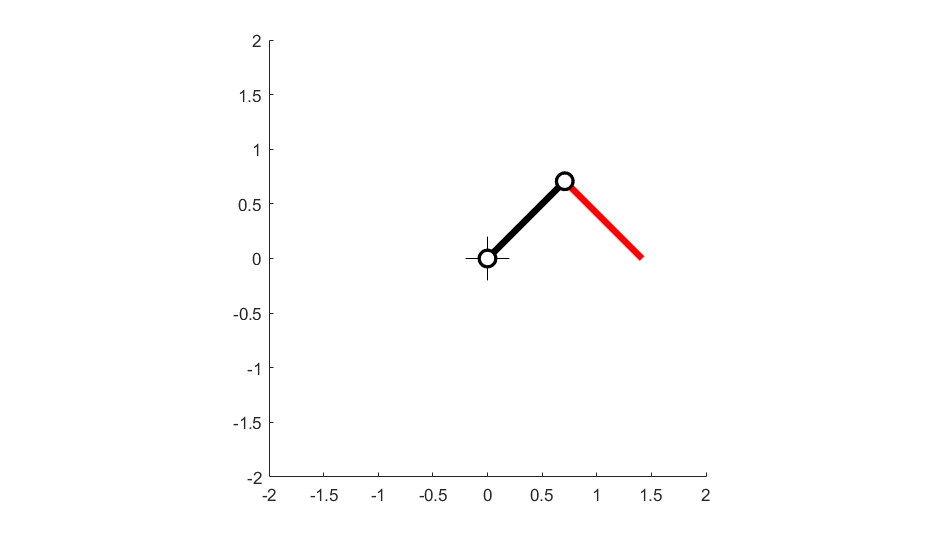

% Initialize coordinates
steps = 200;
indepCoord0 = [pi/2; pi/2];
indepCoord1 = [3*pi/4; pi/4];
theta1 = linspace(indepCoord0(1),indepCoord1(1),steps);
theta2 = linspace(indepCoord0(2),indepCoord1(2),steps);

for k = 1 : steps
    
    % Solve the position problem
    solvePositionProblem(system, [theta1(k); theta2(k)])
    
    viewer.update();
    pause(0.01);

end

### 3. Slider-crank mechanism

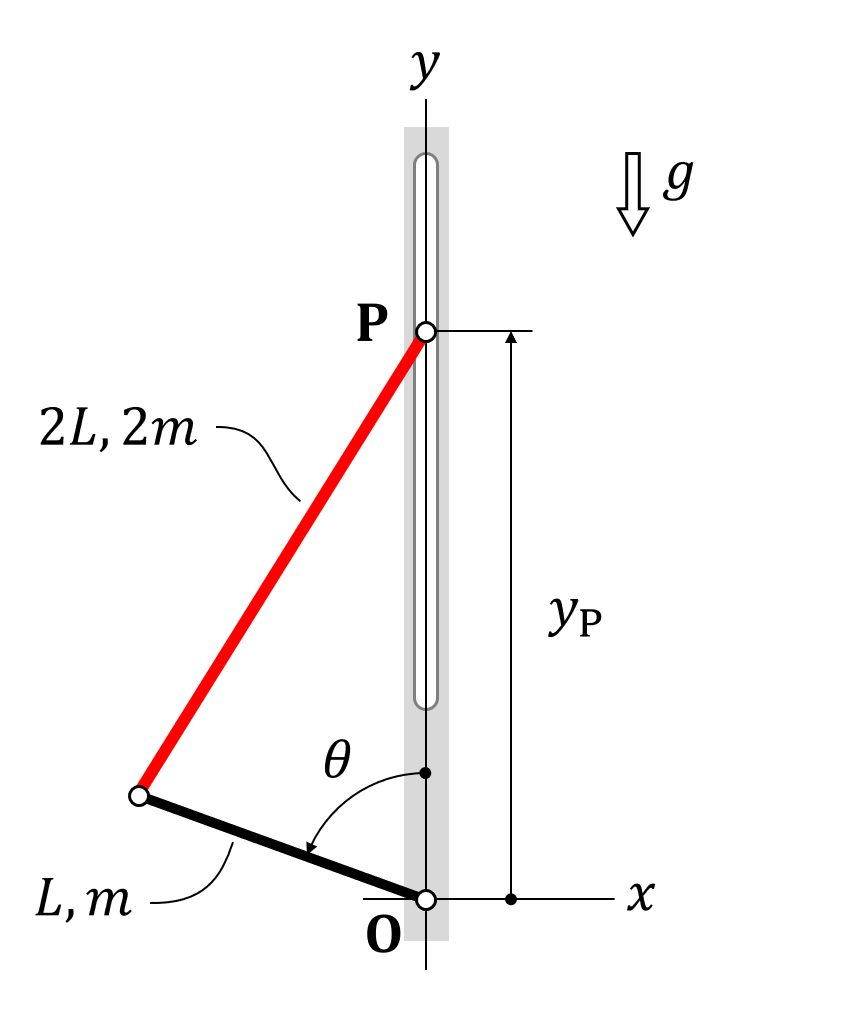

Create a model of the following slider-crack mechanism using a `JointPinSlot`, and define the angle of the crank as independent coordinate.

Then,

- Animate the system for a full rotation of the crank shaft $\theta$.

- Plot the position of the slider $y_{\rm P}$ in terms of the angle of the crank $\theta$.

**Note:** you can use the function `Body.getGeometryAbs()` to obtain the position of the geometry points of a body in the absolute frame of reference (`Model.ground`).

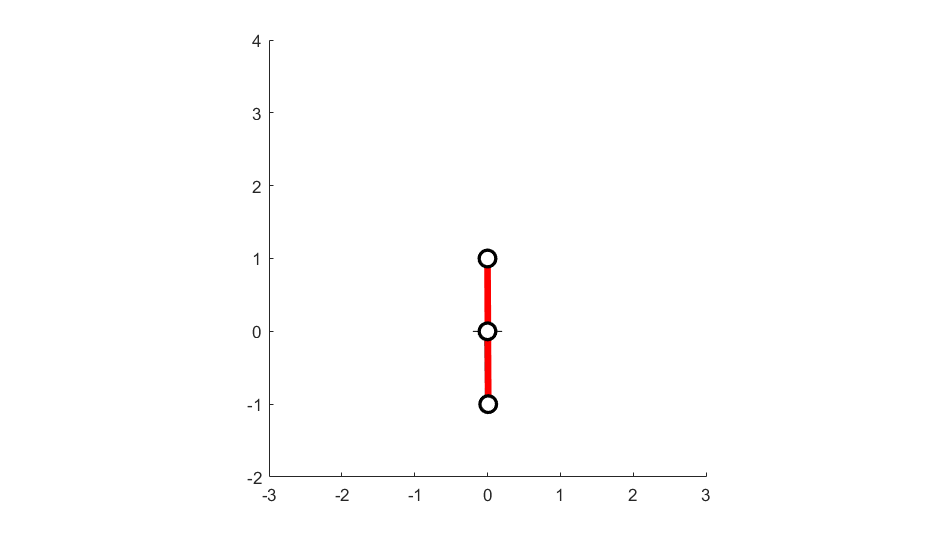

% Initialize model
model = SliderCrank();
viewer = model.initViewer([-3,+3],[-2,+4]);
viewer.showAxes(true);
system = System(model);


% Solve position problem
indepCoord = pi/3;
solvePositionProblem(system, indepCoord);
viewer.update();

% Animate model
steps = 400;
indepCoord0 = 0;
indepCoord1 = 2*pi+0.01;
theta1 = linspace(indepCoord0(1),indepCoord1(1),steps);
angleplot = zeros(k,2);

for k = 1 : steps
    
    % Solve the position problem
    solvePositionProblem(system, theta1(k))
    
    viewer.update();
    sliderYpos = model.bodySet(1, 2).position(2) + sin(model.bodySet(1, 2).angle -3*pi/2);
    angleplot(k,:) = [theta1(k), sliderYpos];

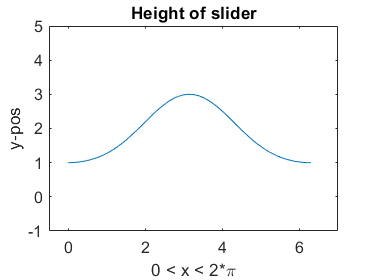

    pause(0.01);
end

% Plot position
f2 = figure;
plot(angleplot(:,1),angleplot(:,2));
title('Height of slider')
xlabel('0 < x < 2*\pi');
ylabel('y-pos');

xlim([-0.5 7]) 
ylim([-1 5])


### **Solve Position Problem Function**

function solvePositionProblem(system, indepCoord)
    % Initialize variables
    q = system.depenCoord;
    deltaq = 1;

    while norm(deltaq) > 10^-6
        
        % Update system coordinates and jacobian matrix
        system.update();
        J = [system.constJacob; system.indepJacob];
        f = [system.constCoord; system.indepCoord - indepCoord];
        deltaq = - J \ f;
        
        % Newton-Raphson Step
        q = q + deltaq;
        system.depenCoord = q;
        
        % Update model
        system.model.update();
    end
end